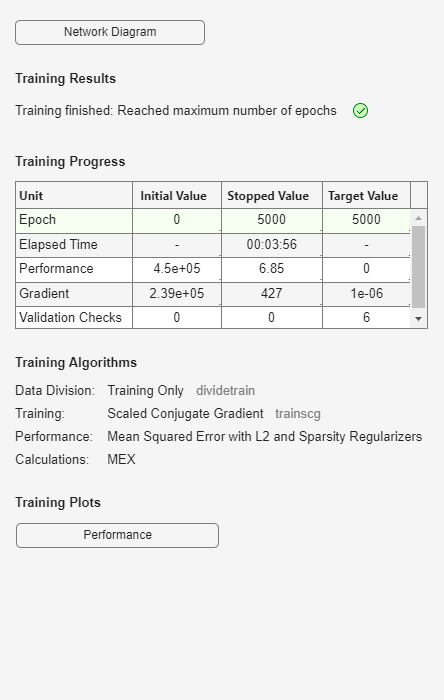

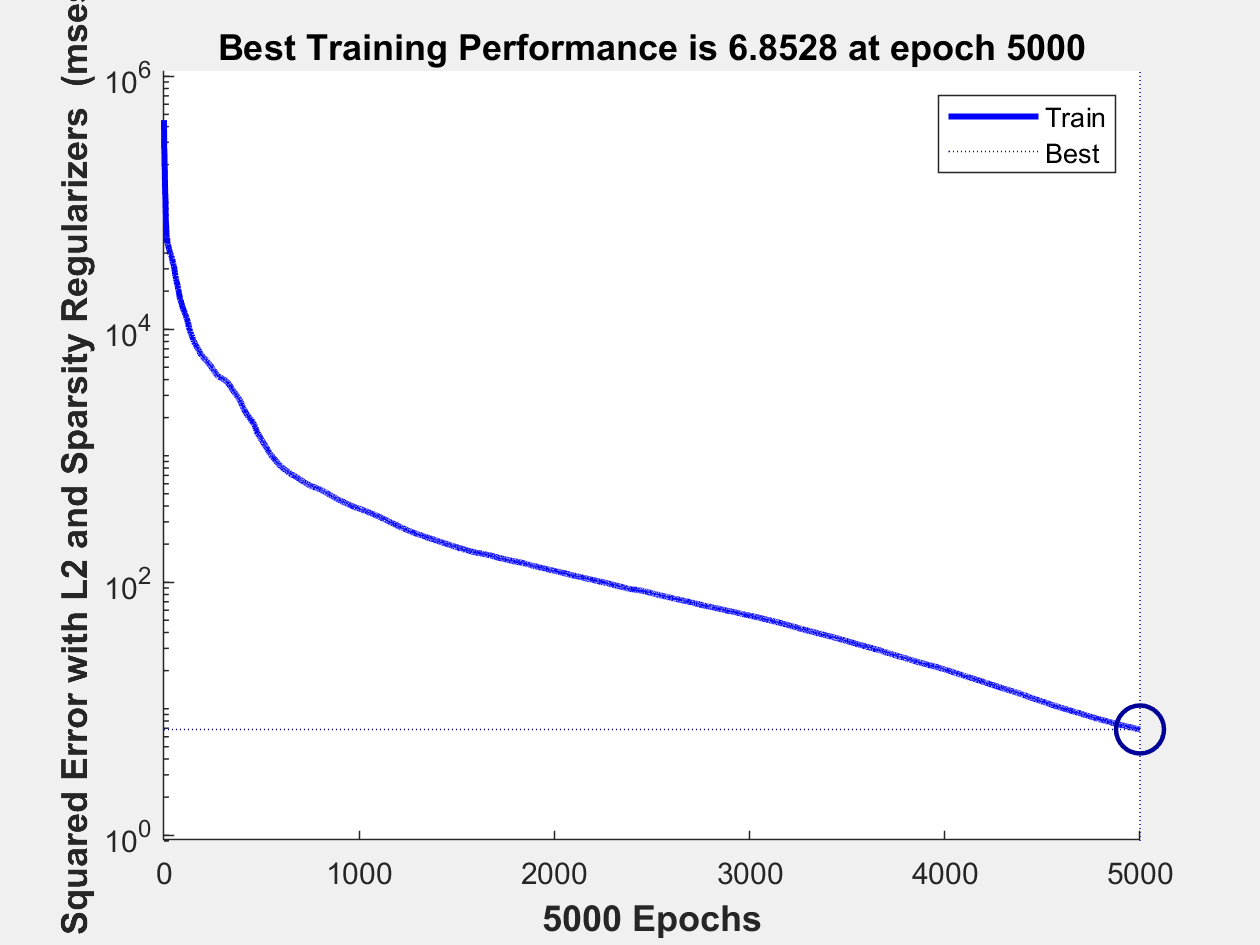


Xdata = specFeatureMatrix';
auto = trainAutoencoder(Xdata,18,'MaxEpochs',5000,...
    'EncoderTransferFunction','satlin',...
    'DecoderTransferFunction','purelin');

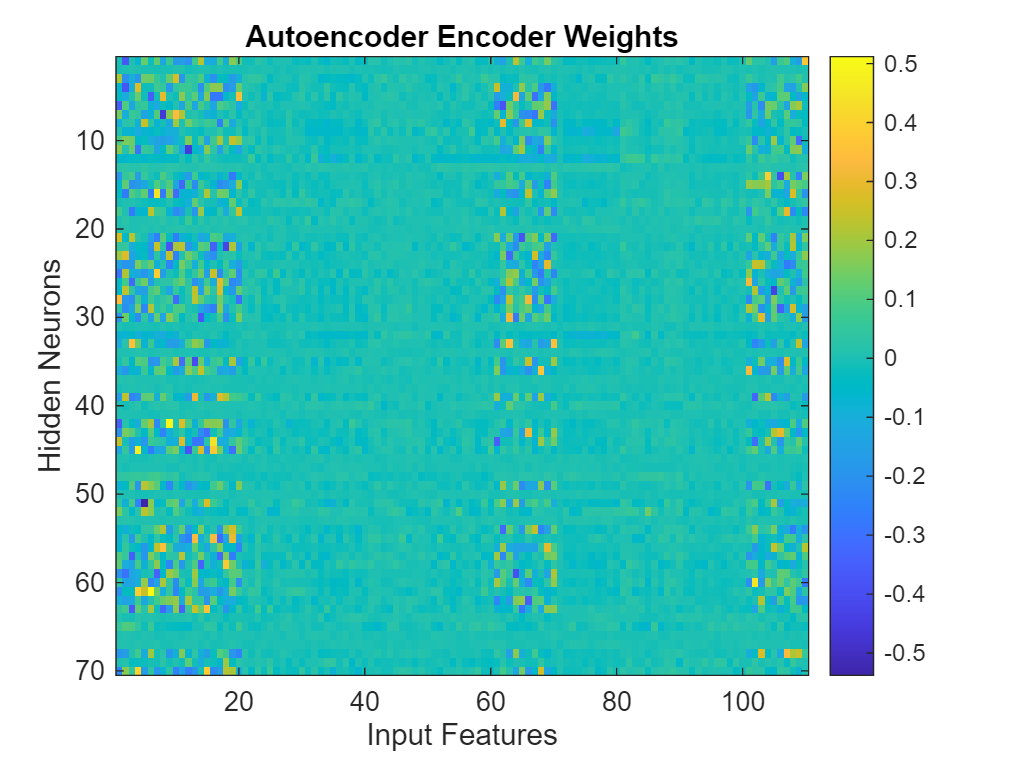

% Visuals Galore

W = auto.EncoderWeights;

% Visualize the autoencoder weights
figure;
imagesc(W);
colorbar;
xlabel('Input Features');
ylabel('Hidden Neurons');
title('Autoencoder Encoder Weights');

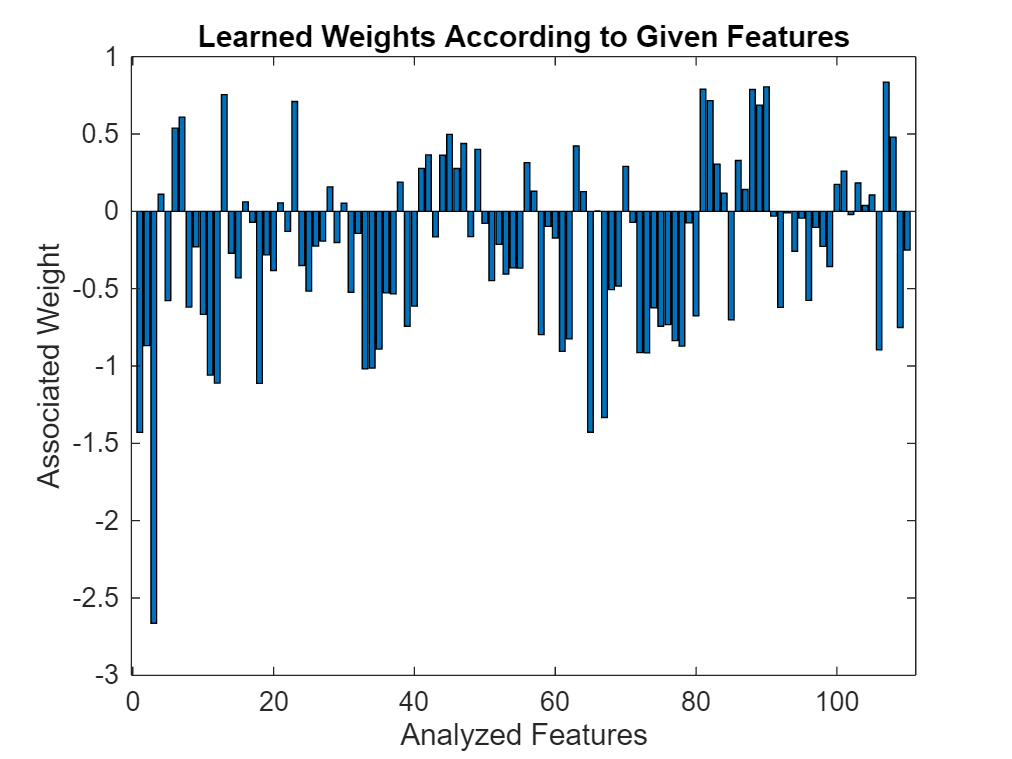


featureNum = size(W, 2); overallWeight = zeros(featureNum,1); colW = [];
for featiter = 1:featureNum
    colW = W(:,featiter);
    overallWeight(featiter) = sum(colW,1);
end
figure;
bar(overallWeight');
title('Learned Weights According to Given Features')
xlabel("Analyzed Features");
ylabel("Associated Weight"); 

SVM Accuracy (Autoencoder Features): 96.49%


Iteration Number 1.000000

SVM Accuracy (Autoencoder Features): 96.94%


Iteration Number 2.000000

SVM Accuracy (Autoencoder Features): 95.35%


Iteration Number 3.000000

SVM Accuracy (Autoencoder Features): 95.86%


Iteration Number 4.000000

SVM Accuracy (Autoencoder Features): 95.12%


Iteration Number 5.000000

SVM Accuracy (Autoencoder Features): 95.36%


Iteration Number 6.000000

SVM Accuracy (Autoencoder Features): 94.65%


Iteration Number 7.000000

SVM Accuracy (Autoencoder Features): 94.45%


Iteration Number 8.000000

SVM Accuracy (Autoencoder Features): 95.16%


Iteration Number 9.000000

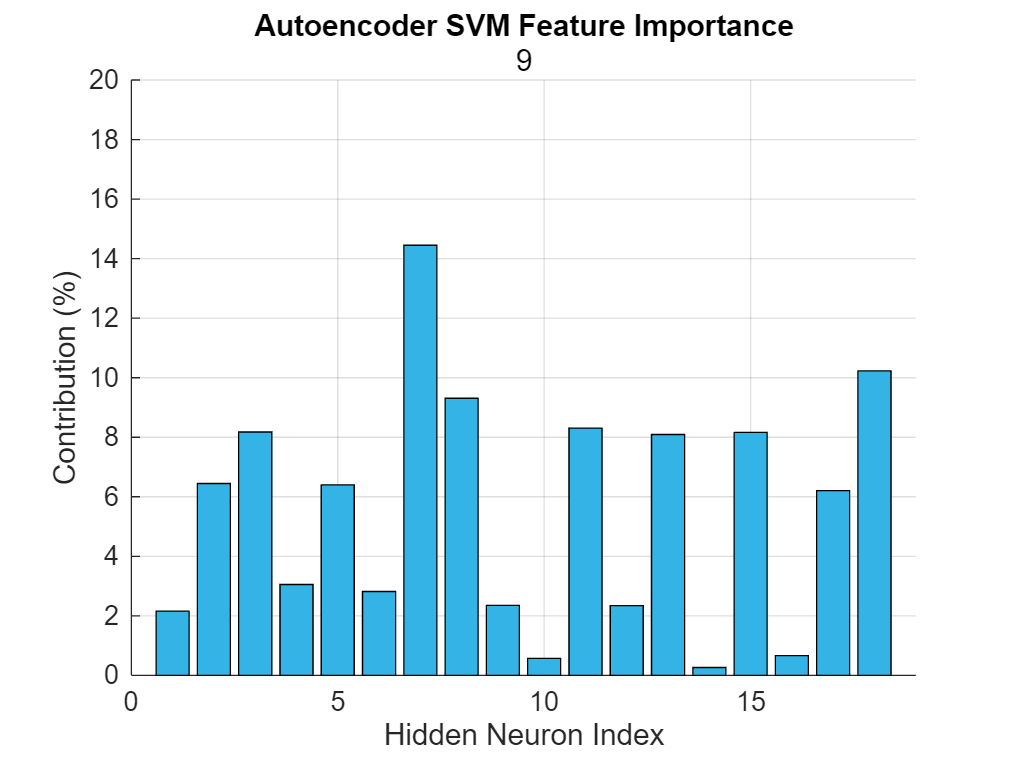


% Encode all features using the trained autoencoder
normalEncodedFeatures = encode(auto, specFeatures');
abnormalEncodedFeatures = encode(auto, abnspecFeatures');

% Combine normal and abnormal features
combinedFeatures = [normalEncodedFeatures, abnormalEncodedFeatures];
combinedFeatures = combinedFeatures';

% Create corresponding labels: 0 for normal, 1 for abnormal
numNormal = size(normalEncodedFeatures, 2);
numAbnormal = size(abnormalEncodedFeatures, 2);
combinedLabels = [zeros(1, numNormal), ones(1, numAbnormal)];

% Convert features to table
featureTableAutoencoder = array2table(combinedFeatures);

% Extract feature matrix and labels
featureMatrixAutoencoder = table2array(featureTableAutoencoder);
labelsAutoencoder = combinedLabels';

% Check for NaNs in the feature matrix
if any(isnan(featureMatrixAutoencoder), 'all')
    error('Feature matrix contains NaN values!');
end

% Normalize features
featureMatrixAutoencoder = normalize(featureMatrixAutoencoder, 'zscore');

perfMod = 0.9; 

% Loop through performance modifiers
for perfModiter = 0.1:0.1:perfMod
    % Split Data
    cv = cvpartition(labelsAutoencoder, 'HoldOut', perfModiter);
    XTrainAuto = featureMatrixAutoencoder(training(cv), :);
    YTrainAuto = labelsAutoencoder(training(cv));
    XTestAuto = featureMatrixAutoencoder(test(cv), :);
    YTestAuto = labelsAutoencoder(test(cv));

    % Train SVM Model with linear kernel
    svmModelAuto = fitcsvm(XTrainAuto, YTrainAuto, 'KernelFunction', 'linear', 'Standardize', true);

    % Predict on Test Data
    YPredAuto = predict(svmModelAuto, XTestAuto);
    accuracyAuto = sum(YPredAuto == YTestAuto) / length(YTestAuto);
    fprintf('SVM Accuracy (Autoencoder Features): %.2f%%\n', accuracyAuto * 100);
    fprintf('Iteration Number %f%\n', perfModiter/0.1);
    
    % Calculate Feature Contributions
    svmWeightsAuto = svmModelAuto.Beta;
    featureContributionAuto = abs(svmWeightsAuto) / sum(abs(svmWeightsAuto)) * 100;

    % Create bar plot that updates smoothly
    clf; % Clear figure for fresh plot
    hold on;

    % Animate the bars growing
    numFeatures = length(featureContributionAuto);
    barHeights = zeros(1, numFeatures);
    numSteps = 20;  % Number of steps for animation

    for step = 1:numSteps
        barHeights = featureContributionAuto * (step / numSteps);
        bar(barHeights, 'FaceColor', [0.2, 0.7, 0.9]);
        % Labels and formatting
        xlabel('Hidden Neuron Index');
        ylabel('Contribution (%)');
        title('Autoencoder SVM Feature Importance',  perfModiter/0.1);
        axis([0 numFeatures+1 0 20]);
        grid on;

        drawnow;  % Forces MATLAB to render the updated bars immediately
    end

    hold off;
end

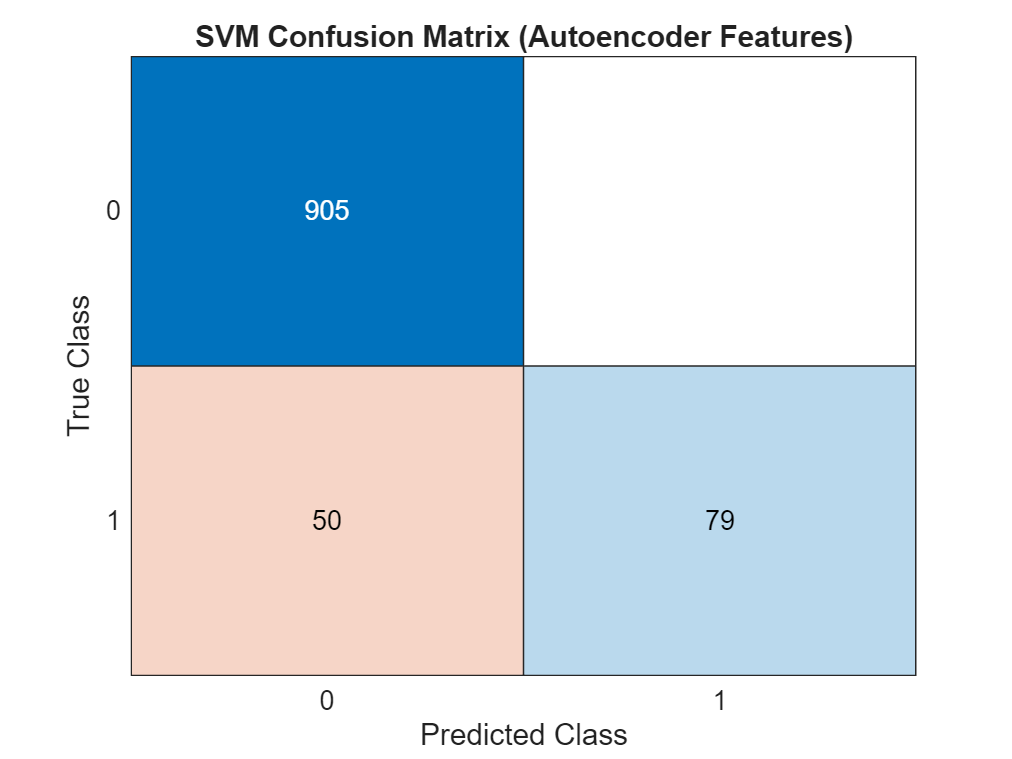

Avg. Overall Accuracy: 94.740000 

% Confusion Matrix didn't want to change in real time with bargraph so %
% it is now in its own space for the time being.                       %
confusionchart(YTestAuto, YPredAuto);
title('SVM Confusion Matrix (Autoencoder Features)'); 